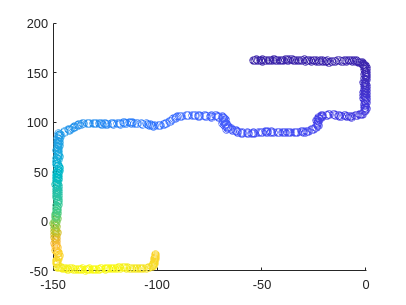

% T = gpslog1;
% lat = T.Lat ./ 1e7
% lon = T.Lon ./ 1e7
% veln = T.VelN ./1e3
% vele = T.VelE ./1e3
% 
% 
% 
% gx = geoaxes;
% geoscatter(gx,lat, lon, 'R','LineWidth',0.2)
% geobasemap(gx,'satellite')
% %axesm('MapProjection','mercator','MapLatLimit',[32.982 32.987],'MapLonLimit',[-96.752 -96.746])
% %axesm('eqaconic','MapLatLimit',[30 60],'MapLonLimit',[-10 10])
% framem; 
% %plotm(lat,lon)
% deltalat = [5 5]; 
% deltalon = [3 3];
% quiverm(lat,lon,veln,vele,'r')
% geoaxes

hold off
K = 5.0;
scatter(report.ukf_x,report.ukf_y,[],report.error)

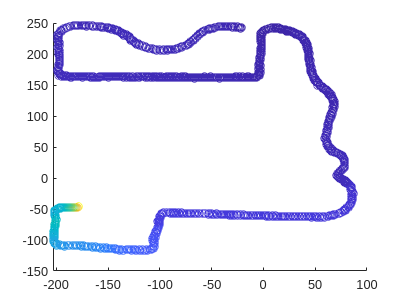

scatter(report_full.ukf_x,report_full.ukf_y,[],report_full.error)

% scatter(report.tru_x,report.tru_y)
% plot(report_full.time, report_full.error,':', 'LineWidth',2)
% hold on
% plot(report_full.time, report_full2.error,':', 'LineWidth',2)
nudge_mean_error = mean(transpose([report_full3_aggr.error, report_full4_aggr.error, report_full5_aggr.error, report_full6_aggr.error]))

nudge_mean_error =        NaN    2.5751    2.5033    2.4518    2.4230    2.4360    2.4536    2.4602    2.4526    2.4519    2.4411    2.4647    2.4585    2.4644    2.4673    2.4773    2.4907    2.4800    2.4791    2.4625    2.4549    2.4649    2.4650    2.4516    2.4302    2.4128    2.4198    2.4116    2.4019    2.3959    2.3944    2.4003    2.4073    2.4073    2.4115    2.4157    2.4223    2.4237    2.4242    2.4173    2.4186    2.4265    2.4220    2.4242    2.4165    2.4092    2.4095    2.4074    2.4061    2.3999


plot(report_full.time, nudge_mean_error,'LineWidth',4,'Color','b')
hold on
nonudge_mean_error = mean(transpose([report_nonudge.error,report_nonudge_2.error,report_nonudge_3.error]))

nonudge_mean_error =     2.7294    2.7003    2.6657    2.7040    2.7138    2.6851    2.6756    2.6817    2.6844    2.6817    2.6886    2.6895    2.6957    2.7009    2.6977    2.7012    2.7027    2.7049    2.6949    2.6945    2.6963    2.6926    2.6933    2.7005    2.6975    2.7006    2.6997    2.7070    2.7102    2.6999    2.6921    2.6989    2.7019    2.7079    2.7073    2.6992    2.7048    2.7055    2.7079    2.7077    2.7082    2.7085    2.7087    2.7065    2.7073    2.7063    2.7096    2.7107    2.7153    2.7149


plot(report_full.time, nonudge_mean_error,'LineWidth',4,'Color','r')
hold on
plot(report_full.time, report_full4_aggr.error,':', 'LineWidth',2,'Color','b')
plot(report_full.time, report_nonudge.error,':', 'LineWidth',2,'Color','r')
plot(report_full.time, report_full5_aggr.error,':', 'LineWidth',2,'Color','b')
plot(report_full.time, report_full6_aggr.error,':', 'LineWidth',2,'Color','b')

plot(report_full.time, report_nonudge_2.error,':', 'LineWidth',2,'Color','r')
plot(report_full.time, report_nonudge_3.error,':', 'LineWidth',2,'Color','r')


legend("Average Corrected Error","Average Uncorrected Error","Corrected Run", "Uncorrected Run")

smoothed_error = movmean(transpose(reportbslow1.current_error), 300)

smoothed_error =     3.1247    3.1215    3.1187    3.1132    3.1097    3.1043    3.0951    3.0863    3.0756    3.0702    3.0618    3.0541    3.0467    3.0341    3.0280    3.0184    3.0095    3.0013    2.9903    2.9760    2.9682    2.9582    2.9492    2.9389    2.9271    2.9195    2.9114    2.8971    2.8878    2.8801    2.8710    2.8591    2.8490    2.8393    2.8305    2.8233    2.8139    2.8042    2.7944    2.7875    2.7781    2.7699    2.7610    2.7520    2.7464    2.7386    2.7291    2.7197    2.7113    2.7038


super_smoothed_error = movmean(transpose(reportbslow1.current_error), 1000)

super_smoothed_error =     1.7275    1.7260    1.7247    1.7228    1.7225    1.7214    1.7204    1.7184    1.7167    1.7161    1.7157    1.7150    1.7146    1.7137    1.7116    1.7116    1.7106    1.7092    1.7072    1.7062    1.7057    1.7039    1.7033    1.7020    1.7014    1.7001    1.6997    1.6996    1.6989    1.6989    1.6982    1.6977    1.6966    1.6958    1.6950    1.6948    1.6934    1.6925    1.6915    1.6913    1.6896    1.6886    1.6879    1.6868    1.6861    1.6852    1.6846    1.6840    1.6840    1.6835


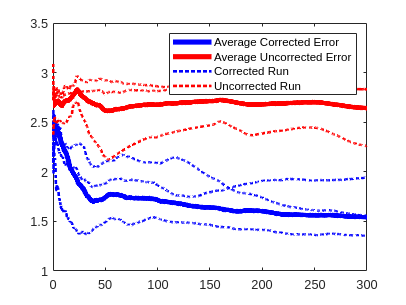

hold off

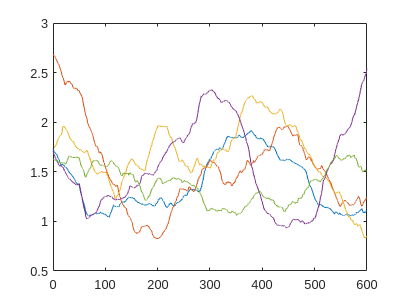

% plot(report_full7_detailed.time, report_slow1.current_error.current_error)

plot(reportbslow1.time, movmean(transpose(reportbslow1.current_error), 1000))
hold on
plot(reportbslow2.time, movmean(transpose(reportbslow2.current_error), 1000))
plot(reportbslow3.time, movmean(transpose(reportbslow3.current_error), 1000))
plot(reportbslow4.time, movmean(transpose(reportbslow4.current_error), 1000))
plot(reportbslow5.time, movmean(transpose(reportbslow5.current_error), 1000))
hold off

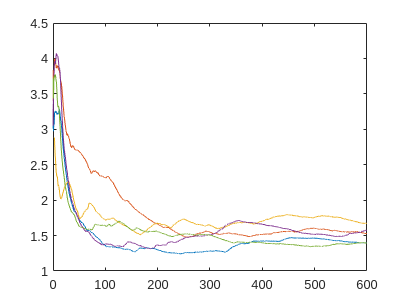

plot(reportbslow1.time, reportbslow1.error)
hold on
plot(reportbslow2.time, reportbslow2.error)
plot(reportbslow3.time, reportbslow3.error)
plot(reportbslow4.time, reportbslow4.error)
plot(reportbslow5.time, reportbslow5.error)
hold off

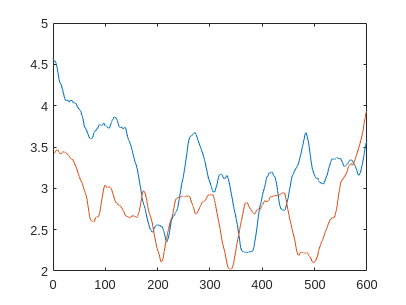

plot(reportdaverage.time, movmean(transpose(reportdaverage.current_error), 1000))
hold on
plot(reportdaverage2.time, movmean(transpose(reportdaverage2.current_error), 1000))
hold off

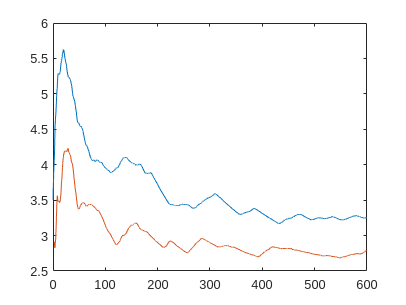

plot(reportdaverage.time, reportdaverage.error)
hold on
plot(reportdaverage2.time, reportdaverage2.error)
hold off


quiver(biases.x, biases.y,biases.cx,biases.cy)
hold on
quiver(biases.x, biases.y,biases.bx,biases.by)
scatter(biases.x,biases.y,[],biases.t)
mean_cx = mean(biases.cx)

mean_cx = -0.1215


mean_cy = mean(biases.cy)

mean_cy = -0.1569

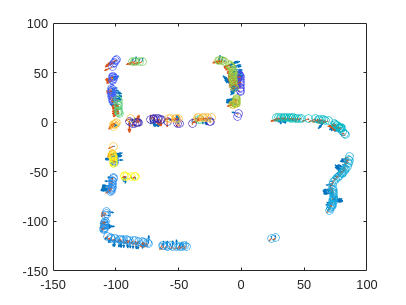

hold off

full_corrections = (biases.bx.^2+biases.by.^2).^0.5

full_corrections =     0.8701
    0.8701
    0.2300
    0.1800
    0.3900
    0.5301
    0.5901
    0.3500
    0.1800
    0.0300


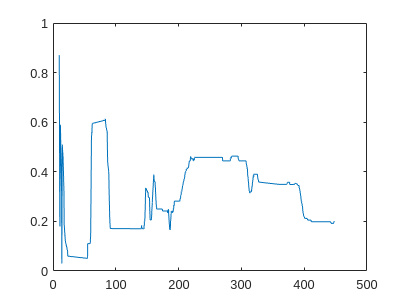

plot(biases.t, full_corrections)

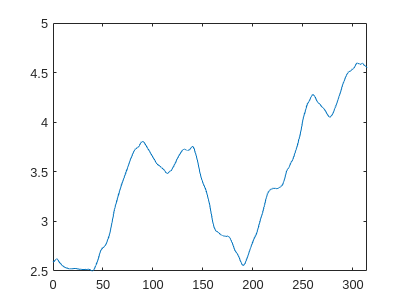

plot(deviationk10.time, movmean(transpose(deviationk10.current_error), 1000))